# Guía 2 - Ejercicio 2

## Enunciado

Implemente un perceptrón simple que aprenda la función lógica XOR de 2 y 4 entradas (utilizando el algorítmo backpropagation).

## Update de a uno

clear all
close all
heta = 0.01;
chico = 0.5;
w_0 = normrnd(0,0.1,[4 2]);%(rand([2 2])-0.5)*chico;
bias_0 = normrnd(0,0.1,[1 4]);%(rand([1 2])-0.5)*chico;
w_1 = normrnd(0,0.1,[4 1]);%(rand([2 1])-0.5)*chico;
bias_1 = normrnd(0,0.1,[1 1]);%(rand([1 1])-0.5)*chico;
x = [-1 -1;...
     -1  1;...
      1 -1;...
      1  1];
errores = [];

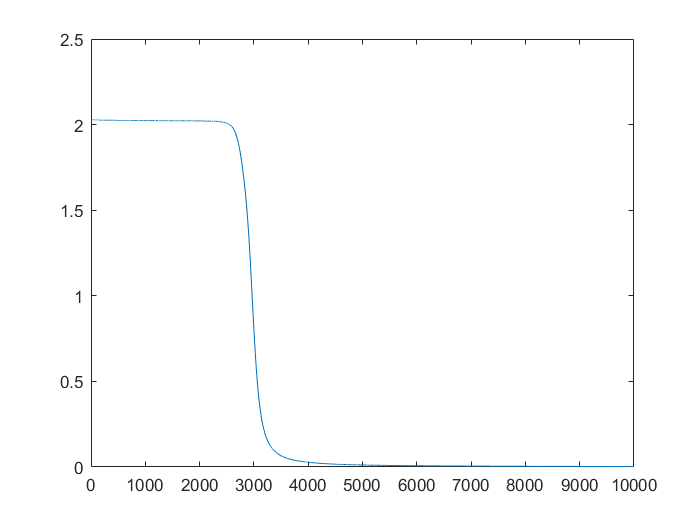

%FORWARD
for j=1:10000
  orden_aleatorio = randperm(4);
  error_acumulado=0;
  for i=1:4
      alguno=orden_aleatorio(i);
      entrada = x(alguno,:);
      V1 = tanh(entrada*w_0'+bias_0);
      salida = tanh(V1*w_1+bias_1);
      if entrada(1) ~= entrada(2)
          y_deseado = 1;
      else
          y_deseado=-1;
      end 
      error = 0.5*(salida-y_deseado)^2;
      %BACK
      dEdbias1 = (salida-y_deseado)*(1-salida^2);
      dEdw1 = dEdbias1*V1';
      dEdbias0 = dEdbias1*w_1'.*(1-V1.^2);
      dEdw0 = dEdbias0'*entrada;
      %UPDATE
      w_0 = w_0-heta*dEdw0;
      bias_0 = bias_0-heta*dEdbias0;
      w_1 = w_1-heta*dEdw1;
      bias_1 = bias_1-heta*dEdbias1;
      error_acumulado = error_acumulado + error;
  end
  errores = [errores error_acumulado];
end
plot(errores)

## Update todos a la vez

clear all
close all
heta = 0.005;
chico = 1;
w_0 = (rand([2 2])-0.5)*chico;
bias_0 = (rand([1 2])-0.5)*chico;
w_1 = (rand([2 1])-0.5)*chico;
bias_1 = (rand([1 1])-0.5)*chico;
x = [-1 -1;...
     -1  1;...
      1 -1;...
      1  1];
errores = [];

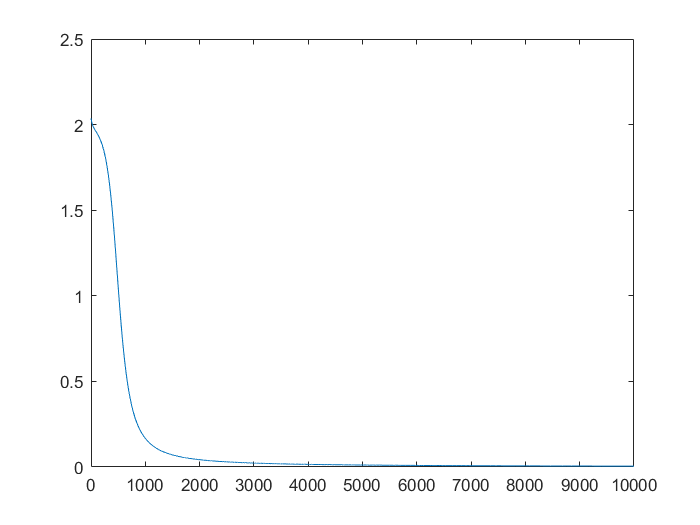

%FORWARD
for j=1:10000
  orden_aleatorio = randperm(4);
  dEdbias1 = 0;
  dEdw1 = 0;
  dEdbias0 = 0;
  dEdw0 = 0;
  error_acumulado=0;
  for i=1:4
      alguno=orden_aleatorio(i);
      entrada = x(alguno,:);
      V1 = tanh(entrada*w_0'+bias_0);
      salida = tanh(V1*w_1+bias_1);
      if entrada(1) ~= entrada(2)
          y_deseado = 1;
      else
          y_deseado=-1;
      end 
      error = 0.5*(salida-y_deseado)^2;
      %BACK
      dEdbias1_partial = (salida-y_deseado)*(1-salida^2);
      dEdw1_partial = dEdbias1_partial*V1';
      dEdbias0_partial = (salida-y_deseado)*(1-salida^2)*w_1'.*(1-(V1).^2);
      dEdw0_partial = dEdbias0_partial'*entrada;
      
      dEdbias1 = dEdbias1+dEdbias1_partial;
      dEdw1 = dEdw1+dEdw1_partial;
      dEdbias0 = dEdbias0 + dEdbias0_partial;
      dEdw0 = dEdw0+dEdw0_partial;
      error_acumulado = error_acumulado + error;

  end
  %UPDATE
  w_0 = w_0-heta*dEdw0;
  bias_0 = bias_0-heta*dEdbias0;
  w_1 = w_1-heta*dEdw1;
  bias_1 = bias_1-heta*dEdbias1;
  
  errores = [errores error_acumulado];

end
plot(errores)

## XOR de 8 entradas

clear all
close all
heta = 0.005;
chico = 0.3;
w_0 = normrnd(0,0.1,[4 6]);%(rand([4 4])-0.5)*chico;
bias_0 = normrnd(0,0.1,[1 6]);%(rand([1 4])-0.5)*chico;
w_1 = normrnd(0,0.1,[6 20]);%(rand([4 8])-0.5)*chico;
bias_1 = normrnd(0,0.1,[1 20]);%(rand([1 8])-0.5)*chico;
w_2 = normrnd(0,0.1,[20 1]);%(rand([8 1])-0.5)*chico;
bias_2 = normrnd(0,0.1,[1 1]);%(rand([1 1])-0.5)*chico;

errores = [];
x = [-1 -1 -1 -1 ;...
     -1 -1 -1  1 ;...
     -1 -1  1 -1 ;...
     -1 -1  1  1 ;...
     -1  1 -1 -1 ;...
     -1  1 -1  1 ;...
     -1  1  1 -1 ;...
     -1  1  1  1 ;...
      1 -1 -1 -1 ;...
      1 -1 -1  1 ;...
      1 -1  1 -1 ;...
      1 -1  1  1 ;...
      1  1 -1 -1 ;...
      1  1 -1  1 ;...
      1  1  1 -1 ;...
      1  1  1  1 ];
 
      

%FORWARD
for j=1:10000
  orden_aleatorio = randperm(16);
  dEdbias1 = 0;
  dEdw1 = 0;
  dEdbias0 = 0;
  dEdw0 = 0;
  error_acumulado=0;
  for i=1:16
      alguno=orden_aleatorio(i);
      entrada = x(alguno,:);
      V1 = tanh(entrada*w_0+bias_0);
      V2 = tanh(V1*w_1+bias_1);
      salida = tanh(V2*w_2+bias_2);
      if sum(entrada)==0
          y_deseado = -1;
      else
          y_deseado=1;
      end 
      error = 0.5*(salida-y_deseado)^2;
      %BACK
      dEdbias2_partial = (salida-y_deseado)*(1-salida^2);
      dEdw2_partial = dEdbias2_partial*V2';
      dEdbias1_partial = dEdbias2_partial*w_2'.*(1-V2.^2);
      dEdw1_partial = V1'*dEdbias1_partial;
      dEdbias0_partial = (1-(V1).^2).*(w_1*dEdbias1_partial')';
      dEdw0_partial = dEdbias0_partial'*entrada;
      
      dEdbias1 = dEdbias1+dEdbias1_partial;
      dEdw1 = dEdw1+dEdw1_partial;
      dEdbias0 = dEdbias0 + dEdbias0_partial;
      dEdw0 = dEdw0+dEdw0_partial;
      error_acumulado = error_acumulado + error;

  end
  %UPDATE
  w_0 = w_0-heta*dEdw0';
  bias_0 = bias_0-heta*dEdbias0;
  w_1 = w_1-heta*dEdw1;
  bias_1 = bias_1-heta*dEdbias1;
  
  errores = [errores error_acumulado];

end
plot(errores(end-10000:end))

Subscript indices must either be real positive integers or logicals.